# Aproximare MCMMP

## Recensământul SUA

Datele de mai jos au fost înregistrate de US Census între 1900 și 2010

%CENSUS - example with census data
%          polynomial fit

%population
y = [ 75.995  91.972 105.711 123.203 131.669 150.697 ...
    179.323 203.212 226.505 249.633 281.422 308.786]';

t = (1900:10:2010)';   % census years

Dorim să modelăm datele și să facem predicții pentru anii 1975 și 2015


x = (1890:1:2019)';    % evaluation years
w = [1975,2015];       % prediction years


Vom modela datele printr-un polinom de gradul 3


$$y=c_{1}t^3+c_{2}t^2+c_{3} t+c_{4}$$


## Fitting direct


c=polyfit(t,y,3)

c =       -6.5861175842884e-06        0.0477331340773929          -108.99621049254          80028.7113025289


Rezultatele sunt inacceptabile din punct de vedere numeric.

Vom normaliza datele cu


$$s=\frac{t-\bar{t}}{\sigma(t)}$$


mt=mean(t); st=std(t);

s=(t-mt)/st;
xs=(x-mt)/st;


## Fitting cu date normalizate

coeficienții

cs=polyfit(s,y,3)

cs =          -0.30870560061877          11.8372207792208          76.5611977154729          166.493214285714


predicțiile

zs=polyval(cs,xs);
est=polyval(cs,(w-mt)/st);

reprezentare grafică

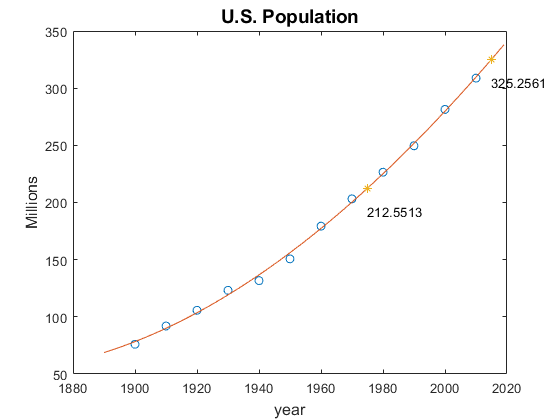

plot(t,y,'o',x,zs,'-',w,est,'*')
for i=1:length(w)
    text(w(i),est(i)-20,num2str(est(i)))
end
title('U.S. Population', 'FontSize', 14)
xlabel('year', 'FontSize', 12)
ylabel('Millions', 'FontSize', 12)